% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % %
% Program to find energy eigenvalue and eigenfunction of quantum harmonic %
% oscillator using Numerov with bisection root finding method.            %                                                           
%                                                                         %
% Programmed by Anthony Knighton on 2/26/2021                             %
% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % %
clear all;
E(1)=input('Energy of Lower Bracket =>');
E(2)=input('Energy Upper Bracket =>');
symmetric = false;
anti_symmetric = false;
found = false;
xmax=5;
tollerance = 1e-8;
h = 0.001;
% Initial Lower bound
[x,psi] = qmho_numerov(E(1),xmax,h);
N=size(x,2);
error_L=(psi(N)-psi(N-1))/(x(N)-x(N-1));
error_L2=psi(N);
if abs(error_L) < tollerance
    found = true;
    symmetric = true;
    EM = E(1);
elseif abs(error_L2) < tollerance
    found = true;
    anti_symmeric = true;
    EM = E(1);
end
% Initial Upper bound
if not(found)
   [x,psi] = qmho_numerov(E(2),xmax,h);
   error_U=(psi(N)-psi(N-1))/(x(N)-x(N-1));
   error_U2=psi(N);
   if abs(error_U) < tollerance
      found = true;
      symmetric = true;
      EM = E(2);
   elseif abs(error_U2) < tollerance
      found = true;
      anti_symmeric = true;
      EM = E(2);
   end
   if error_U*error_L<0
      symmetric = true;
   elseif error_U2*error_L2<0
      anti_symmetric = true;
      error_U = error_U2;
      error_L = error_L2;
   else
      error('Blacket is incorrect. Claculation cannot proceed.');
   end
   if symmetric & anti_symmetric
      error('Both symmetric & anti-symmetric:?');
   end
end
% Bisection Method
while not(found)
    EM = sum(E)*0.5;
    [x,psi] = qmho_numerov(EM,xmax,h);
    if symmetric
        error_M=(psi(N)-psi(N-1))/(x(N)-x(N-1));
    else
        error_M=psi(N);
    end
    if abs(error_M)<tollerance
        found = true;
    else
        if error_M*error_L < 0
            E(2) = EM;
            error_U = error_M;
        else
            E(1) = EM;
            error_L = error_M;
        end
    end
end
% Display the Results
if symmetric
    fprintf('Symmetric state: ')
elseif anti_symmetric
    fprintf('Anti-Symmetric state: ')
end

Symmetric state: 

fprintf('Eigenvalue= %.6f\n', EM);

Eigenvalue= 1.000564


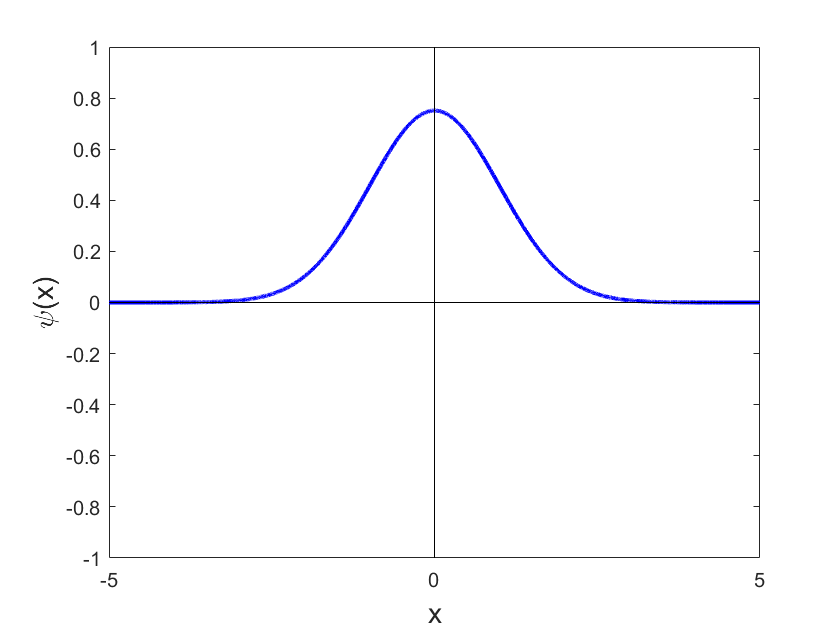

X(1:N) = x(1:N);
X(N+1:2*N-1)=-x(N-1:-1:1);
if symmetric
    Y(1:N) = psi(1:N);
    Y(N+1:2*N-1)=psi(N-1:-1:1);
else
    Y(1:N) = psi(1:N);
    Y(N+1:2*N-1)=-psi(N-1:-1:1);
end
A = sum(Y(1:2:2*N-3).^2+4*Y(2:2:2*N-2).^2+Y(3:2:2*N-1).^2)*h/3;
Y = Y / sqrt(A);
p=plot(X,Y,[-xmax,xmax],[0,0],[0,0],[-1,1]);
set(p(1),'linewidth',2,'color','blue')
set(p(2:3),'color','black')
xlabel('x','fontsize',14)
ylabel(texlabel('psi(x)'),'fontsize',14)

function [x,psi]=quantum_ho_numerov(E,xmax,h)
W=@(x) -(x^2-E);
N=round(xmax,h);
xmax=h*N;
x=linspace(-xmax,0.0,N+1);
w=-x.^2+E
psi=zeros(N+1)
psi(1)=0;
psi(2)=0.001;
% Numerov method
   for n=2:N
       psi(n+1)=2*(1-5*h^2*w(n)/12)*psi(n)-(1+h^2*w(n-1)/12)*psi(n-1);
       psi(n+1)=psi(n+1)/(1+h^2*w(n+1)/12);
   end
end